## Script DMC

clear all; clc;
load('GPlanta.mat');

### Planta

G11 = G(1,1)

G11 =
 
                   0.3764
  exp(-9.61*s) * -----------
                 190.2 s + 1
 
Continuous-time transfer function.



G22 = G(2,2)

G22 =
 
                   0.2333
  exp(-15.9*s) * -----------
                 150.2 s + 1
 
Continuous-time transfer function.



### Resposta ao Step

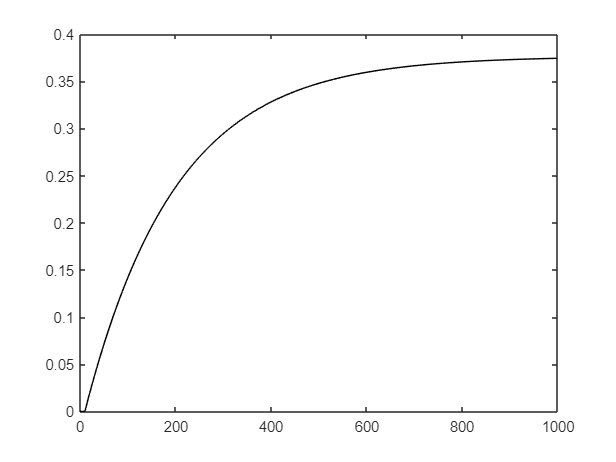

t = 0:2:1000;

u = ones(1,length(t));

y_step = lsim(G11,u,t);
plot(t,y_step,'k-');

#### Coeficientes "S" da resposta ao degrau unitário

S_n = y_step(2:end); 

#### Matriz S

Np = 11;    %H Predição
M = 2;      %H Controle
S = toeplitz(S_n(1:Np),[S_n(1) zeros(1,Np-1)])

S =          0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0
    0.0008         0         0         0         0         0         0         0         0         0         0
    0.0047    0.0008         0         0         0         0         0         0         0         0         0
    0.0086    0.0047    0.0008         0         0         0         0         0         0         0         0
    0.0124    0.0086    0.0047    0.0008         0         0         0         0         0         0         0
    0.0162    0.0124    0.0086    0.0047    0.0008         0         0         0         0         0        

S_simplificado = toeplitz(S_n(1:Np),[S_n(1) zeros(1,M-1)])

S_simplificado =          0         0
         0         0
         0         0
         0         0
    0.0008         0
    0.0047    0.0008
    0.0086    0.0047
    0.0124    0.0086
    0.0162    0.0124
    0.0200    0.0162


### Função Objetivo